# **Simulações de antenas *****microstrip***** com células SRR para 5G**

`por Renan Machado`

Este é um *live script* em MatLAB que visa construir um *dataset* de simulações de antenas com metamateriais para treinar modelos preditivos de *machine learning*. Os parâmetros dos metamateriais, como largura e comprimento da célula, disposição do arranjo, e outros, serão variados em uma faixa de valores adequados, procurando respeitar as referências oferecidas pela literatura. O *software* utilizado para as simulações eletromagnéticas é o **CST Studio Lite©**, utilizando o módulo **Microwave Studio**. Para o controle automatizado do software, será utilizada a API desenvolvida por Symeon Symeonidis, Stefanos Tsantilas e Stelios Mitilineos, tendo o código fonte e a documentação disponíveis [aqui](https://github.com/simos421/CST-MATLAB-API). A API original foi modificada e está disponível no repositório.

## Inicialização do CST

Para correta utilização da API, antes é necessário adicionar seu código fonte ao *path*, dessa forma:

addpath(genpath('CST-MATLAB-API-master'));

Para iniciar a aplicação do CST, utilizamos o seguinte comando:

cst = actxserver('CSTStudio.application');

Agora, com o CST aberto, podemos inicializar o Microwave Studio.

mws = cst.invoke('NewMWS');

Você deve ter na sua tela algo parecido como a figura abaixo.

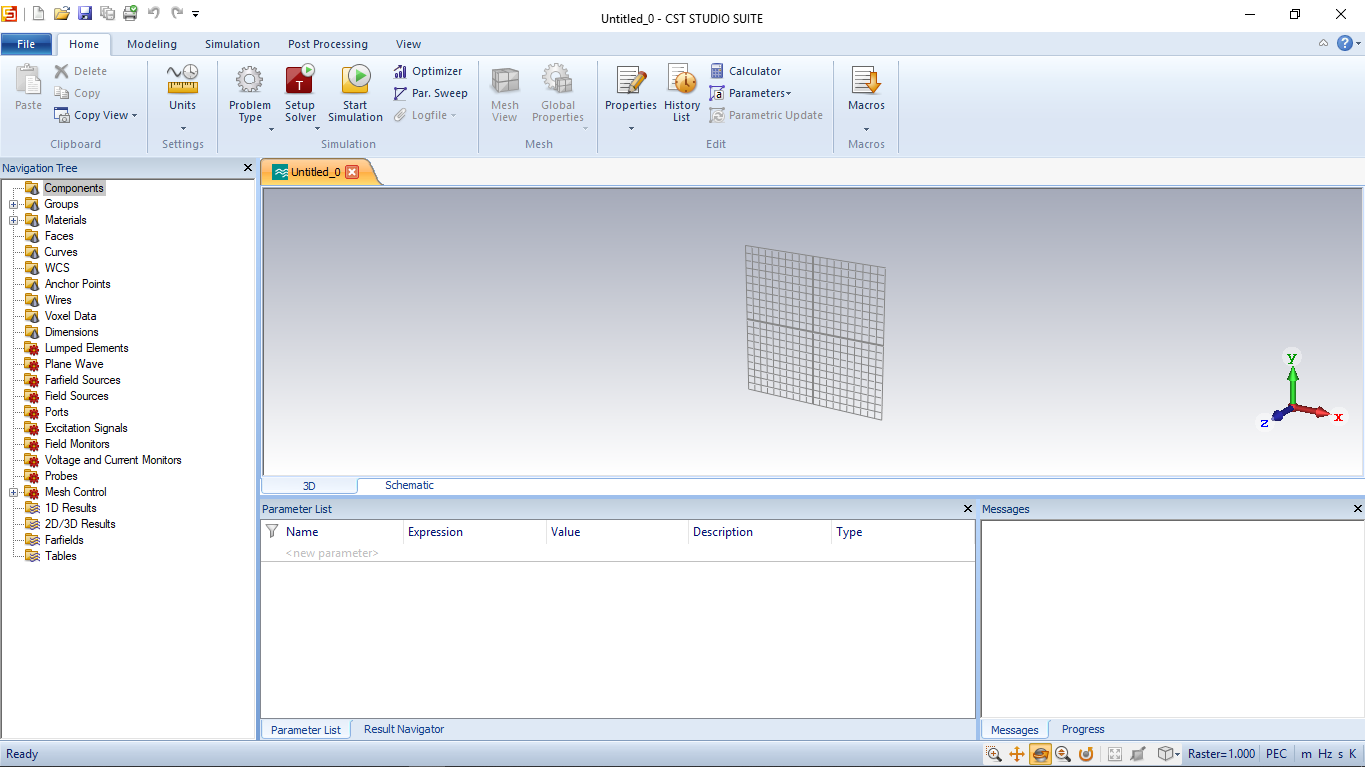

## Configurando o ambiente de simulação

Na MCW (*Mobile World Congress*) de 2019, o presidente da ANATEL, Leonardo de Morais, anunciou o leilão de 200 MHz na frequência de 3,5 GHz que serão destinados para implantação do 5G no Brasil. Aqui, a frequência será esse domínio reservado na frequência de 3.5GHz que a ANATEL anunciou. 

Inicialmente, precisamos definir as unidades padrão. É importante ressaltar que a **unidade de comprimento é micrometros** (1e-6 metros). Com isso, também é necessário definir o intervalo de frequência que será simulado, aqui serão simulados 3% da frequência central como limites inferior e superior. Assim, é possível inicializar a *mesh* e definir as condições de contorno.

fcenter = 3.5;
fmin = fcenter * 0.97

fmin = 3.3950

fmax = fcenter * 1.03

fmax = 3.6050

Em código:

CstDefineUnits(mws, 'um', 'GHz', 's', 'Kelvin', 'V', 'A', 'Ohm', 'S', 'PikoF', 'NanoH');
CstDefineFrequencyRange(mws, fmin, fmax);
CstMeshInitiator(mws); 

A antena estará no espaço livre, então:

%Condições de contorno
Xmin = 'expanded open';
Xmax = 'expanded open';
Ymin = 'expanded open';
Ymax = 'expanded open';
Zmin = 'expanded open';
Zmax = 'expanded open';

CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);

Em seguida, precisamos definir o material do fundo:

XminSpace = 0;
XmaxSpace = 0;
YminSpace = 0;
YmaxSpace = 0;
ZminSpace = 0;
ZmaxSpace = 0;

CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);

## Definição de materiais

Para a definição de materiais que serão utilizados nos componentes, é preciso definir as propriedades do material de acordo com a biblioteca do CST e fazer uma função em MatLAB com todas essas propriedades, juntamente com o nome do material. Somente depois disso é que podemos utilizar o nome do material no código. Na API, já temos funções para definir materiais como cobre e FR4 com perdas.

metal = CstCopperAnnealedLossy(mws)

metal = 'Copper (annealed)'

[dieletric, epsilon_r] = CstFR4lossy(mws)

dieletric = 'FR-4 (lossy)'

epsilon_r = 4.3000

Além disso, precisamos definir a altura da folha de metal (nesse caso, cobre).

t = 0.035*1e3; % in um (t from thickness)

## *Design* da antena base

Na criação do *dataset*, os metamateriais serão aplicados em uma antena base que possui bons parâmetros. Essa antena será projetada com base em toda a referência bibliográfica existente. No *design *de antenas, é necessário definir primariamente o material do substrato e a frequência de aplicação. A altura do substrato também precisa ser predefinida com antecedência. A bibliografia sugere uma escolha entre $0,03\lambda$ e $0,5\lambda$, tendo uma preferência por substratos mais finos por resultarem em uma melhor eficiência de radiação. Para esse projeto:

h = 1700; % in um (1e-6 meters)

As variáveis associadas a geometria de uma antena *microstrip* são essas mostradas na figura abaixo. 

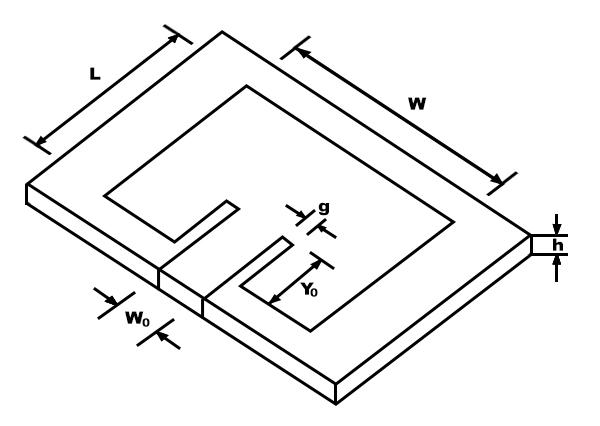

Para uma obtermos uma boa eficiência de radiação, (BALANIS, 2005) nos dá que:


$$W=\frac{c}{2f_r }\sqrt{\;\frac{2}{{\epsilon \;}_r +1}}$$


W = 0.9*3e8/(2*fcenter*1e9)*sqrt(2/(epsilon_r+1))*1e6 % in um

W = 2.3694e+04

Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

epsilon_reff = 3.8595

Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

delta_l = 779.4965

Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 0.98.*3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

l = 1.9820e+04

Por último, os parâmetros restantes normalmente são:


$$Y_0 =4h$$



$$g\approx 1000\;\mathrm{um}$$



$$W_0 =3,5g$$


Y0 = 4*h

Y0 = 6800

g = 1000;
W0 = 3.5*g

W0 = 3500

Para refletir essas medidas no CST, usamos:

DrawMicrostripAntenna(mws, W, l, t, h, Y0, W0, g, metal, dieletric);
DrawPort(mws, W, l, t, h, W0);

## Simulação da antena base

Vamos agora definir o monitor de campo distante (*farfield*) na frequência de ressonância. Aqui um passo manual precisa ser dado, já que os *templates* de pós-processamento são uma *feature* relativamente nova, o controle VBA desse componente não está disponível na API. 

Para criar esse *template*, adicione um *breakpoint* (clicando sobre o número da linha) na linha comentada para parar a execução do código. Abra o CST no menu superior, selecione a aba ***Post Processing > Result Templates > Template Based Post Processing***. Na primeira caixa, selecione ***Farfield and Antenna Properties*** e na segunda ***Farfield Result***. Selecione o *template ****Max Gain over Frequency*** e renomeie-o para ***Gain***, clicando duas vezes sobre o item. Após isso, clique em ***Close*** e continue com a execução do código.

Não se esqueça de definir o caminho onde serão exportados os resultados modificando a função *ExportResults*.

CstDefineFarfieldMonitor(mws,strcat('farfield (f=',num2str(fcenter),')'), fcenter);
                    
%Create template for Gain vs Frequency (name it Gain)

CstDefineTimedomainSolver(mws,-40);

ExportResults(mws, 'C:\Users\Renan\results', 0, W, l, t, h, Y0, W0, g);

CstDeleteComponent(mws, 'component1');

## Intervalo de valores para a célula metamaterial

As variáveis associadas a geometria de uma célula metamaterial quadrada são mostradas na figura abaixo.

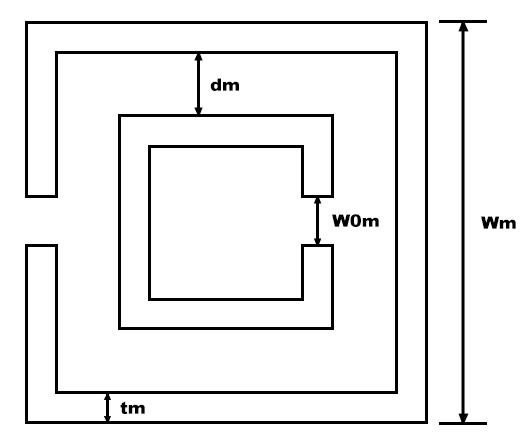

De acordo com a literatura, as células metamteriais apresentam suas características DNG (Double Negative) para intervalos de:


$$0,05\lambda \le W_m \le \frac{\lambda }{4}$$



$$t_m \approx 0,1W_m$$



$$1,9\times {10}^{-3} \lambda \le W_{0m} \le 7,6\times {10}^{-3} \lambda$$



$$1,9\times {10}^{-3} \lambda \le d_m \le 5,7\times {10}^{-3} \lambda$$


Alguns intervalos estão em função do comprimento de onda $\lambda$, de forma que:


$$\lambda =\frac{c}{f}$$


lambda = 3e5./fcenter % in um (1e-6 m)

lambda = 8.5714e+04

n_Wm = 4;

Wm_min = 0.05*lambda;
Wm_max = 1/4*lambda;
Wm_step = (Wm_max-Wm_min)/(n_Wm-1);
Wm = Wm_min:Wm_step:Wm_max

Wm = 	1.0e+04 *

    0.4286    1.0000    1.5714    2.1429


tm = 0.1.*Wm

tm = 	1.0e+03 *

    0.4286    1.0000    1.5714    2.1429


n_W0m = 4;

W0m_min = 1.9e-3*lambda;
W0m_max = 7.6e-3*lambda;
W0m_step = (W0m_max-W0m_min)/(n_W0m-1);
W0m = W0m_min:W0m_step:W0m_max

W0m =   162.8571  325.7143  488.5714  651.4286


n_dm = 4;

dm_min = 1.9e-3*lambda;
dm_max = 5.7e-3*lambda;
dm_step = (dm_max-dm_min)/(n_dm-1);
dm = dm_min:dm_step:dm_max

dm =   162.8571  271.4286  380.0000  488.5714


n_sim = n_Wm*n_W0m*n_dm

n_sim = 64

De acordo com a literatura, temos que:


$$0,003\lambda \;\le h\le 0,05\lambda$$


hmin = 0.003;
hmax = 0.05;
h_step = (hmax - hmin)/(4 - 1);

[h_factor, h] = GetAntennaValues(hmin, hmax, h_step, lambda)

h_factor =     0.0030    0.0187    0.0343    0.0500


h = 	1.0e+03 *

    0.2651    0.2575    0.2503
    1.6495    1.6023    1.5577
    3.0339    2.9471    2.8651
    4.4183    4.2918    4.1725


Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

epsilon_reff =     4.1993    4.2019    4.2044
    3.8679    3.8759    3.8836
    3.6860    3.6951    3.7039
    3.5670    3.5762    3.5852


Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

delta_l = 	1.0e+03 *

    0.1239    0.1204    0.1171
    0.7569    0.7358    0.7158
    1.3629    1.3257    1.2905
    1.9423    1.8904    1.8413


Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

l = 	1.0e+04 *

    2.0666    2.0667    2.0667
    2.0278    2.0297    2.0316
    1.9597    1.9644    1.9688
    1.8807    1.8882    1.8952


Por último, os parâmetros restantes normalmente estão nessa faixa de valores:


$$h\le Y_0 \le 3h$$



$$2h\le W_0 \le 2\ldotp 2h$$



$$0,2W_0 \le g\le 0,3W_0$$


y0min = 1;
y0max = 3;
[h_rows, h_cols] = size(h);
y0_step = (y0max - y0min)/(h_rows-1);

[y0_factor, y0] = GetAntennaValues(y0min, y0max, y0_step, h)

y0_factor =     1.0000    1.6667    2.3333    3.0000


y0 = 	1.0e+04 *

    0.0265    0.0258    0.0250
    0.2749    0.2670    0.2596
    0.7079    0.6876    0.6685
    1.3255    1.2876    1.2517


w0min = 2;
w0max = 2.2;
w0_step = (w0max - w0min)/(3 - 1);

[w0_factor, w0] = GetAntennaValues(w0min, w0max, w0_step, h)

w0_factor =     2.0000    2.1000    2.2000


w0 = 	1.0e+03 *

    0.5302    0.5150    0.5007
    3.4639    3.3648    3.2712
    6.6745    6.4835    6.3032


gmin = 0.2;
gmax = 0.3;
g_step = (gmax - gmin)/(length(w0_factor)-1);

[g_factor, g] = GetAntennaValues(gmin, gmax, g_step, w0)

g_factor =     0.2000    0.2500    0.3000


g = 	1.0e+03 *

    0.1060    0.1030    0.1001
    0.8660    0.8412    0.8178
    2.0024    1.9451    1.8910


Vamos transformar todos os parâmetros que estão em forma de matriz em um array linear através da função *Flat. *Essa função também remove os valores duplicados e ordena do menor para o maior.

H = Flat(h(1,:))

H =   250.3477
  257.5107
  265.0957


L = Flat(l(1,:))

L = 	1.0e+04 *

    2.0666
    2.0667
    2.0667


Y0 = Flat(y0(:,1))

Y0 = 	1.0e+04 *

    0.0265
    0.2749
    0.7079
    1.3255


W0 = Flat(w0)

W0 = 	1.0e+03 *

    0.5007
    0.5150
    0.5302
    3.2712
    3.3648
    3.4639
    6.3032
    6.4835
    6.6745


G = Flat(g)

G = 	1.0e+03 *

    0.1001
    0.1030
    0.1060
    0.8178
    0.8412
    0.8660
    1.8910
    1.9451
    2.0024


## Intervalo de valores para as células SRR

% TODO

## Simulação

O número de simulações rodadas é:

n_sim = length(H)*length(L)*length(Y0)*length(W0)*length(G)

Variando os parâmetros:

count = 1;
for h = 1:length(H)
    for l = 1:length(L)
        for y0 = 1:length(Y0)
            for w0 = 1:length(W0)
                for g = 1:length(G)
                    DrawMicrostripAntenna(mws, W, L(l), t, H(h), Y0(y0), W0(w0), G(g), metal, dieletric);
                    DrawPort(mws, W, L(l), t, H(h), W0(w0));
                    
                    CstDefineFarfieldMonitor(mws,strcat('farfield (f=',num2str(fcenter),')'), fcenter);
                    
                    %Create template for Gain vs Frequency (name it Gain)
                    
                    CstDefineTimedomainSolver(mws,-40);
                    
                    ExportResults(mws, 'C:\Users\Renan\results', count, W, L(l), t, H(h), Y0(y0), W0(w0), G(g));
                    
                    CstDeleteComponent(mws, 'component1');
                    
                    %Emulate enter key press
                    
                    count = count + 1;
                end
            end
        end
    end
end